# **Neural Network: Training Script**

**Author: Samer A. Mohamed (https://github.com/SamMans)**

## Build Network

clear
clc

Determine the project folder that you want to load:

folder = "char_class";
load(pwd + "\" + folder + "\dataset\train.mat");
load(pwd + "\" + folder + "\dataset\cross_v.mat");
load(pwd + "\" + folder + "\dataset\test.mat");
Dim = [size(X, 2), num_labels]; %--> Network dimensions

Select number of layers (hidden layers, excluding input and output layers):

L = 1;

Select number of activation units (per hidden layer):

unit_no = 20;
Dim = int16([Dim(1), unit_no * ones(1, L), Dim(end)]); %--> Dimensions

Select activation function:

activ_fn = "sigmoid";
activ_layers = strings(1, L + 2); activ_layers(:) = activ_fn; 
Network = NN(Dim, activ_layers, num_labels); %--> Create network object

Press run button to build network:

## Train & Validate Network

Select maximum number of iterations:

max_iter = 50;
Network = set_max_iter(Network, max_iter);

Adjust your resularization parameter "lambda":

lambda = 2.2;
Network = set_lambda(Network, lambda);

Determine the approximate number of points you need for your learning curve:

point_num = 60;
% Generate data points
while(rem(size(X, 1), point_num) ~= 0)
    point_num = point_num + 1; %--> Make sure the data set is divisible by data points
end
increment = size(X, 1) / point_num; %--> Jumps between training set portions
points = zeros(point_num, 2);

Press the run button to train network and visualize diagnostics:

 
% Successive training and learning curve generation
fprintf('Training progress: ');

Training progress: 

for i = 1 : point_num
    % Train using the current portion of the data set
    Train_net = Network; %--> Training network for extracting learning curve
    Train_net = set_data(Train_net, X(1 : i * increment, :));
    Train_net = Train(Train_net, y(1 : i * increment, :)); %--> Train the network
    
    % Get the training errors for this portion
    Train_net = set_lambda(Train_net, 0.0); %--> Ignore regularization for now
    Train_net = cost(Train_net, y(1 : i * increment, :)); %--> Update cost
    Train_net = set_train_cost(Train_net); %--> Set training cost
    points(i, 1) = get_train_cost(Train_net); %--> Record cost

    % Get cross validation errors for this portion
    Train_net = set_data(Train_net, Xcv); %--> Set cross-validation data
    Train_net = cost(Train_net, ycv); %--> Update cost
    Train_net = set_cv_cost(Train_net); %--> Set cross-validation cost diagnostic
    points(i, 2) = get_cv_cost(Train_net); %--> Record cost

    % Show training progress
    fprintf('\b\b\b\b%d%%', round((i * 100) / point_num));
end

100%

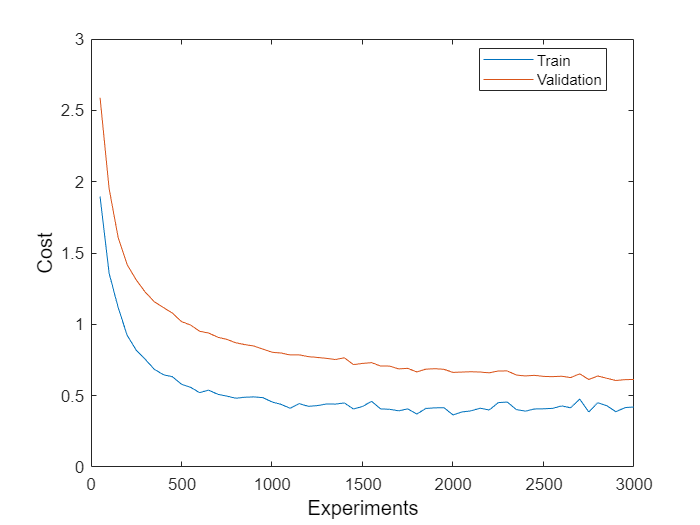


% Plot learning curve
plot(increment : increment : size(X, 1), points);
xlabel('Experiments','FontSize', 12, 'Color', 'k')
ylabel("Cost", 'FontSize', 12, 'Color', 'k')
legend('Train','Validation', 'Location', 'Best')

Train_net = set_lambda(Train_net, lambda); %--> Restore regularization parameter

% Classification accuracy 
p = get_pred(Train_net); %--> Get prediction "Hypothesis"
[~, p] = max(p, [], 2); %--> Get classification results
acc = ((size(ycv, 1) - nnz(p - ycv)) / size(ycv, 1)) * 100; %--> Accuracy
Train_net = set_cv_acc(Train_net, acc); %--> Set cross-validation accuracy
disp("Classification Accuracy: " + string(acc) + "%");

Classification Accuracy: 91.5%


## Test Network

Press the test button to get test results:

 
% Get test metrics for the network
Train_net = set_data(Train_net, Xtest); %--> Set test data
Train_net = cost(Train_net, ytest); %--> Update cost
p = get_pred(Train_net); %--> Get prediction "Hypothesis"
[~, p] = max(p, [], 2); %--> Get classification results
acc = ((size(ytest, 1) - nnz(p - ytest)) / size(ytest, 1)) * 100; %--> Accuracy
disp("Testing Accuracy: " + string(acc) + "%");

Testing Accuracy: 90.4%


## Saving Network

If you wish to save the network for later use, type its name and click save:

 
name = "net1";
save(pwd + "\" + folder + "\networks\" + name + ".mat");